Satellite Orbit Simulation

This program is intended to allow the user to manipulate a satellite's orbit and cause it to self-destruct

Jack Rogers

May 8, 2025

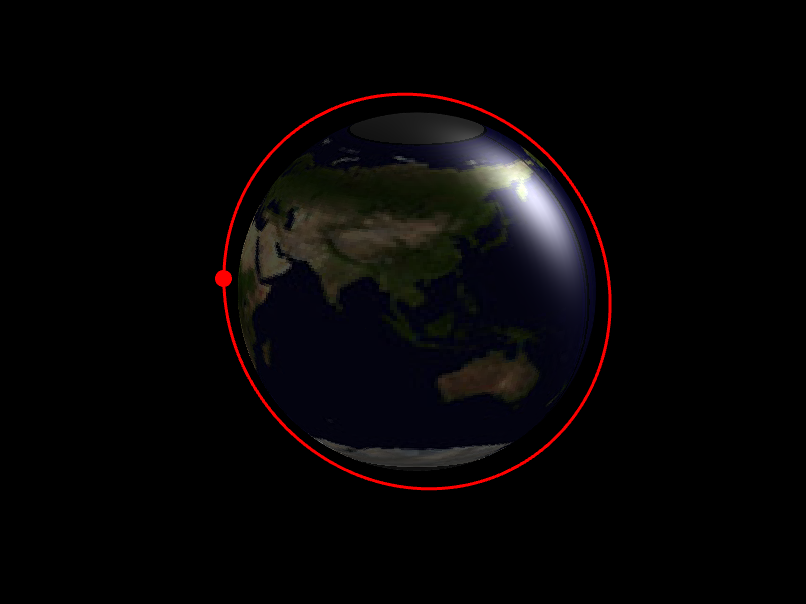

Press 1 for Low Earth Orbit


Press 2 for Gravity Assist


Press 3 for Polar Orbit


Press 4 to self-destruct when prompted


ans = 35

Polar OrbitComplete.


clear 
clc 
clf
% 3D Model of Earth 

% Create figure 
figure('Color', 'k') % Black Background 

% Load Earth image as texture 
earth = imread('EarthTopography.jpg'); % File from NASA

% Create Sphere Data 
[xx, yy, zz] = sphere(100); % 100 points for a smoother sphere 

% Earth Radius 
Radius = 6371; % Units in kilometers 
xx = Radius * xx; 
yy = Radius * yy; 
zz = Radius * -zz; 

% Plot Earth with texture 
surface = surf(xx, yy, zz, 'FaceColor', 'texturemap', ... 
    'CData', earth, ...
    'EdgeColor', 'none'); 

% View Settings 
axis equal 
view(3) 
axis off 
camlight headlight 
lighting gouraud 
rotate3d on % Allow user to rotate Earth interactively 
title('3D Model of Earth') 

% Create Satellite 
while true 
    disp('Press 1 for Low Earth Orbit'); 
    disp('Press 2 for Gravity Assist'); 
    disp('Press 3 for Polar Orbit'); 
    disp('Press 4 to self-destruct when prompted'); 
    choice = input('Orbit Choice: '); 

    switch choice 
        case 1
            simulate_orbit('Low Earth Orbit', 400, 7.8, 'equatorial'); 
            break;
        case 2 
            simulate_orbit('Gravity Assist', 10000, 11.2, 'gravity assist'); 
            break;
        case 3 
            simulate_orbit('Polar Orbit', 800, 7.5, 'polar');
            break;
        otherwise
            disp('Invalid number. Please try again.'); 
    end 
end 


% Satellite Self-Destruct 
while true 
    selfDestructCommand = input('Self-Destruct: ');

    switch selfDestructCommand 
        case 4 
            disp('Satellite self-destructed. Exiting Simulation.'); 
            break; 
        otherwise 
            disp('Invalid choice. Please try again.'); 
    end 
end 

Satellite self-destructed. Exiting Simulation.


function simulate_orbit(orbitType, altitude, speed, mode)
% satellite_simulation(); Redraw Earth

% Set Orbit Parameters
% All parameters explained in satellite_data.csv
Radius = 6371; orbitRadius = Radius + altitude; 
theta = linspace(0, 2*pi, 500); 
hold on; 

switch mode 

    case 'equatorial'
        x = orbitRadius * cos(theta); 
        y = orbitRadius * sin(theta); 
        z = zeros(size(theta)); 

    case 'gravity assist'
        theta = linspace(-1, 1, 300); 
        x = 3 * altitude -(Radius + 8000) * cosh(theta); 
        y = (Radius + 8000) * sinh(theta);
        z = zeros(size(theta)); 
        
    case 'polar' 
        theta = linspace(0, 2*pi, 300); % Full orbit path 
        x = orbitRadius * cos(theta); 
        y = zeros(size(theta)); % Remain in the y = 0 plane 
        z = orbitRadius * sin(theta); % Motion in z-direction
end 


% Initialize Satellite Marker 
h = plot3(NaN, NaN, NaN, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); 
trail = animatedline('Color', 'r', 'LineWidth', 1.5); 
hold off; 

% Set Up Logging 
filename = 'satellite_data.csv'; 
if isfile(filename) 
    delete(filename); % Start fresh 
end 
fid = fopen(filename, 'w'); 
fprintf(fid, 'Distance_km, Speed_km/s, orbitType\n')
fclose(fid); 

% Animate satellite orbit 
for i = 1:length(x) 
    set(h, 'XData', x(i), 'YData', y(i), 'ZData', z(i)); 
    addpoints(trail, x(i), y(i), z(i)); 
    drawnow; 
    pause(0.01); 

    % Log Data 
    distance = norm([x(i), y(i), z(i)]) - Radius; 
    log_data(distance, speed, orbitType); 

    % Exit Check 
    if ~ishandle(h) % Figure Closed 
        return; 
    end 
end 

disp([orbitType 'Complete.']); 
end 

function log_data(distance, speed, orbitType)
data = table(distance, speed, {orbitType}, ... 
    'VariableNames', {'Distance_km', 'Speed_km/s', 'Orbit_Type'}); 
writetable(data, 'satellite_data.csv', 'WriteMode', 'append'); 
end 


